UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

# *Laboratory 3: Fixed Point Method*

## **Name: Juan Camilo Jaimes Ávila**

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab3_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab3_name_lastname.rar*** and subject **Analisis_Lab3_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

-  To understand the fixed point method.

-  To apply the fixed point method.

-  To implement the fixed point method in Matlab. 

-  To interpret problems which can be solved by the fixed point method.

-  To propose problems in which the fixed point method can be used.

## Guide functions:

You will be introduced to some functions that may be useful for the development of this laboratory. You **DO NOT **have to use them if you do not requier them. This is with the purpose of providing a guide for you to understand Matlab and start coding more eficciently.

**Note:** Remember to save your Matlab functions as '.m' files.

- If an array X already exists, you can use it to increase the size of the array and append other elements to the array. For example, **X(end+1) = 5** increases the length of X by 1 and adds a new element to the end of X.

- **sum: S = sum(A)** returns the sum of the elements of A in the first dimension of the array whose size is greater than 1. If A is a vector, sum(A) returns the sum of the elements.

- **diff:** Use the diff function to approximate partial derivatives with the syntax **Y = diff(f)**, where f is a vector of function values evaluated on some domain, X.

- **syms: **`syms ``var1 ... varN `creates symbolic scalar variables `var1 ... varN` of type `sym`. Separate the different variables with spaces. This syntax clears all previous definitions of `var1 ... varN`.

- **Plot:** **plot(X,Y)** creates a 2D line plot of the data in Y versus the corresponding values in X.

You can change the color or style of lines or add markers by including an optional line specification when calling the plot function. For example:

':' represents a dotted line.

'g:' represents a green dotted line.

'g:*' represents a green dotted line with star markers.

'*' represents star markers without a line.

- **hold on:** hold on sets the axis hold state to on, which preserves the current axis graphs so that new graphs added to the axes do not override existing graphs.

- **hold off:** hold off sets the hold state of the axes to off so that new graphs added to the axes will clear existing graphs and reset all axis properties.

## **Practice: **

#### Implementing 

- (0.5 points) Create a Matlab function called *my_fixed point_function_name_lastname()* to find a fixed point of a function over an initial point. The arguments of the function must be: the function to be evaluated $ g(x)$ (as an inline function), the initial iteration point $p_0$, and the desired number of iterations. For instance, the sentences to find the fixed point of $ 1 - x^2/4$ should look like:

g = @(x) 1 - (x.^2)/4;
p0=0.5;
Iter=5;
P=my_fixed_point_function_Juan_Jaimes(g,p0,Iter)

Iteración 1: p = 0.937500
Iteración 2: p = 0.780273
Iteración 3: p = 0.847793
Iteración 4: p = 0.820312
Iteración 5: p = 0.831772


P =    0.831772214446262


- (0.5 points) Create a Matlab function called *Verification_fixed_point_function_name_lastname()* to show if the function has a fixed point over a range, and if that fixed point method converge.

g = @(x) 1 - (x.^2)/4;
p0=0.5;
a = 0;
b = 1;
[B,O]=Verification_fixed_point_function_Juan_Jaimes(g,p0,a,b)

ans = "dentro del rango"

B = logical
   1


O =    0.828427124746190


*B* is a boolean variable.

-  (0.5 points) Create a Matlab function called *visual_verification_name_lastname()* to show the iterations behavior of the fixed point function. The arguments of the function must be: the function to be evaluated $g\left(x\right)$ (as an inline function), the initial point of the range $a$, and the final point of the range $b$, to show the plot, and the iterations $P_k$. Uncomment the details section to show the arrows of the path of each iteration 

For instance, the sentences to visually verify if the function of the exercise in the last point has an unique fixed point should look like,

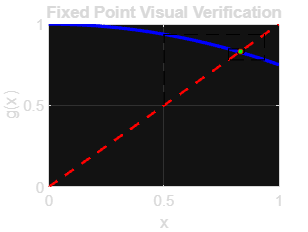

g = @(x) 1 - (x.^2)/4;
a=0;
b=1;
p0 = 0.5;
it =  5;
visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,it)



%%% Details
%%% Use this part of the code to show the details
% x = linspace(a,b,100);
% y = g(x);
% for k = (2:6)
%     hold on
%     plot([x,y],[y,y]);  
%     x = y;
%     y = g(x);
%     plot([x,x],[x,y])
%     hold off
% end

-  (0.5 points) Solve  $g\left(x\right)=-4+4x-\frac{1}{2}x^2$ over [1,5], use 5 iterations in each point.

a) (0.1 points) Show that P = 2 and P = 4 are fixed point using the created function *visual_verification_name_lastname().(Graph1)*

*b) (0.2 points) Use the starting value p0 = 1.9 and show p1,p2,p3,p4 and p5 using *the created function *visual_verification_name_lastname().(Graph2).*

*c) (0.2 points) Use the starting value p0 = 3 and show p1,p2,p3,p4 and p5 using *the created function *visual_verification_name_lastname().(Graph3).*

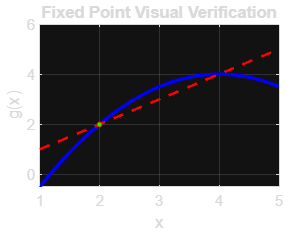

%%% a)
g = @(x) -4 +4*x-(x.^2)/2;
a=1;
b=5;
it=5;
p0=2;
visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,it);

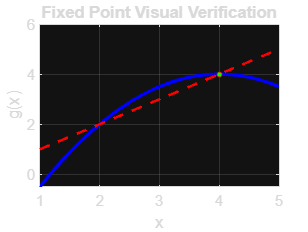


g = @(x) -4 +4*x-(x.^2)/2;
a=1;
b=5;
it=5;
p0=4;
visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,it);

%%% b)
g = @(x) -4 +4*x-(x.^2)/2;
a=1;
b=5;
it=5;
p0=1.99;
P=my_fixed_point_function_Juan_Jaimes(g,p0,100) %%% Doesn't converge

Iteración 1: p = 1.979950
Iteración 2: p = 1.959699
Iteración 3: p = 1.918586
Iteración 4: p = 1.833858
Iteración 5: p = 1.653914
Iteración 6: p = 1.247940
Iteración 7: p = 0.213082
Iteración 8: p = -3.170374
Iteración 9: p = -21.707131
Iteración 10: p = -326.428299
Iteración 11: p = -54587.430298
Iteración 12: p = -1490112126.998800
Iteración 13: p = -1110217081474891776.000000
Iteración 14: p = -616290983999313215385734614626598912.000000
Iteración 15: p = -189907288479420875220940243293583780022667921983518885963309114799947776.000000
Iteración 16: p = -18032389108802991465288892460856918722651774098102779471806570593547797619376831955874911754689292943012379388226041402742279598403864038998016.000000
Iteración 17: p = -162583528485638381765246603121283950608527464504885864531684798049845940806726631194987068052114003260351668406371155036103881058725625842796852090310812105560299760086210203012450916744096130637902026622277941335744588680915356924672347043984639500782016150475020864

P =   -Inf


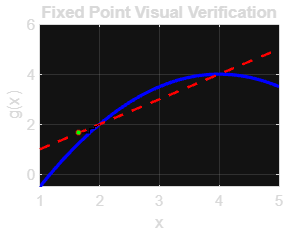

visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,it);

%%% c)
g = @(x) -4 +4*x-(x.^2)/2;
a=1;
b=5;
it=5;
p0=4;
visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,it);

#### **Interpreting**

The network bandwidth allocation problem is one of the central issues in modern communication networks. When a data rate is allocated to a source participating in a network, it derives a utility, which is modeled as a value of a concave function. The well known utility function of each source $s$ is given by the following function, which satisfies the strict concavity, for all $x\in R_+$,

$u_s \left(x\right)=\omega_{s\;} \;\log \;x$  (1)

where $\omega_s \;>0$ is the weighted parameter for the source $s$, and $x$ is the allocated data rate to the network. The share allocated data rate to each source must be regulated with a control mechanism to prevent network congestion. A network congestion is generated when the utility of any source in the network is equal to the allocated data rate in the network.

(1.0) Use the created functions to find the allocated data rate $x$ which could generate a network congestion due to a source with $\omega_{s\;} =4\ldotp 8$, where $x\in$ [5, 15]. Choose the initial point $p_0$.

g = @(x) 4.8*log(x);
p0=14;
a=5;
b=16;
Verification_fixed_point_function_Juan_Jaimes(g,p0,a,b)

ans = "dentro del rango"

ans = logical
   1


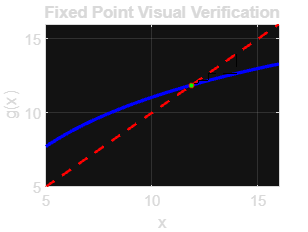

visual_verification_fixed_point_Juan_Jaimes(g,a,b,p0,30)